clear 
% Donnees

J  = 250;
Bt = 250;
Ka = 5000;
Kt1 = 1000;
Kt3 = 1000;

## 1. �tude en boucle ouverte

%2.1
% open('elevateur_NL_BO.slx')

delta_e_0    = 0;
deltadot_e_0 = 0;

T = [-750 -250 -50 0 50 250 750] ;

figure
hold on;
for i = 1:length(T)
    current_d = 0;
    current_T = T(i);
    sim('elevateur_NL_BO_Devoir_1.slx');
    plot(ScopeData.time, ScopeData.signals.values);
    ScopeData.signals.values(end)
end

ans = -0.2937

ans = -0.1438

ans = -0.0414

ans = 0

ans = 0.0414

ans = 0.1438

ans = 0.2937

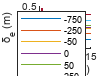


legend("-750", "-250", "-50", "0", "50", "250", "750")
xlabel("Temps (s)")
ylabel("δ_e (m)")

hold off


%1.4 resolution des points d'equilibre 

syms x
solve(Kt3*x^3 + Ka*abs(x)*x + Kt1*x == 0,x)

$$ans = \left(\begin{array}{c} 0\\ -\frac{\sqrt{29}\,\mathrm{i}}{2}-\frac{5}{2}\,\mathrm{i}\\ \frac{\sqrt{29}\,\mathrm{i}}{2}+\frac{5}{2}\,\mathrm{i} \end{array}\right)$$


%1.5 resolution des points d'equilibre pour differents valeur de T
for i = 1:length(T)
    solve(Kt3*x^3 + Ka*abs(x)*x + Kt1*x -T(i) == 0,x)

$$ans = \left(\begin{array}{c} 0\\ -\frac{\sqrt{29}\,\mathrm{i}}{2}-\frac{5}{2}\,\mathrm{i}\\ \frac{\sqrt{29}\,\mathrm{i}}{2}+\frac{5}{2}\,\mathrm{i} \end{array}\right)$$

end



## 2. Lin�arisation

%3.1
%3.2
%3.3
%3.4
ue = [-750 -250 -50 0 50 250 750] ;
delta_ee = sign(ue).*sqrt(abs(ue)./Ka)

delta_ee =    -0.3873   -0.2236   -0.1000         0    0.1000    0.2236    0.3873



%3.5

%3.6

%3.7

%3.8
delta_e = [linspace(0,0.5,1000) 1/160];
%lambda =

A = [0 1 ;4 -1 ];
B = [0 ; 0.004]; 
C = [1 0];
D = 0;

tf(ss(A,B,C,D))

## 3. Synth�se d'un correcteur par placement de p�les

%4.1
%4.2


ans =
 
   0.004
  -------
  s^2 + s
 
Continuous-time transfer function.
Model Properties


%4.3

%4.4

%4.5
syms s
p = expand((s+12)*(s+12+12j)*(s+12-12j))

$$p = s^{3}+36\,s^{2}+576\,s+3456$$

%4.6
%open('elevateur_L_BF.slx')
Ki = 864000;
Kd = 8750;
Kp=144000;

## 4. Implantation d'un correcteur

% 5.1
%open('elevateur_NL_BF.slx')

% 5.2

% 5.3

% 5.4
